# `Datos de la planta`

`En términos generales, para una válvula de salida que corresponde a una abertura de tubo de 1/2 pulgadas, su resistencia es de 1550[s/m^2]`

R=3550;
R1=0.01*R;   %La llave del centro está a un 50% del valor
R2=0.41*R;  %La llave de salida está a un 25% del valor
d1=0.263;   %Unidades en metros
d2=0.263; %Unidades en metros
C1=pi*(d1/2)^2;
C2=pi*(d2/2)^2;
Entrada_caudal=0.0001622; %Unidades en m^3/s Maximo caudal de casa de Sebas

## Función de transferencia

s=tf('s');
sys=R2*Entrada_caudal/((R1*R2*C1*C2*s^2)+(((R1*C1)+(R2*C1)+(R2*C2))*s)+1)

sys =
 
          0.2361
  -----------------------
  152.5 s^2 + 160.1 s + 1
 
Continuous-time transfer function.



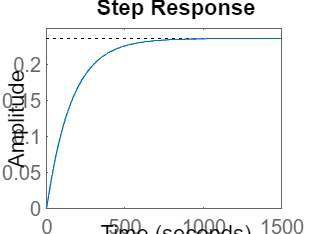


h =

	resppack.timeplot



h=stepplot(sys)

Medida experimentalmente

fileID = fopen('Datos_prueba6.txt','r');
formatSpec = '%f';
A = fscanf(fileID,formatSpec)

A =          0
    0.5000
    0.7200
    0.9500
    8.7900
    1.8100
    1.3800
    0.7200
    0.5000
    8.9300


T=0:1:370

T =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


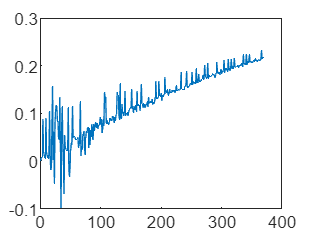

%Llave R2 cerrada 22°
A=A/100;
x=sgolayfilt(A, 1,3);
plot(T,A)

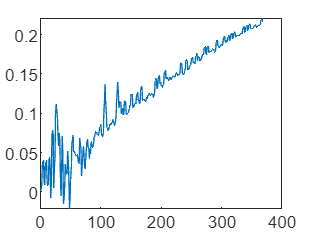

plot(T,x)


%Obtenemos FT
VF=0.2166

VF = 0.2166

Veinteseis=0.264*VF

Veinteseis = 0.0572

% % Interpolacion
% y0 = 80;
% y1 = 80.5;
% x = 0.0660;
% x0 = 0.0640;
% x1 = 0.0664;
% y = y0 + ((y1-y0)/(x1-x0))*(x-x0)

tn=87;
Wn=1/tn

Wn = 0.0115

Ke=VF/Entrada_caudal

Ke = 1.3354e+03

Gs=(Wn^2*Ke)/(s+Wn)^2

Gs =
 
            0.1764
  ---------------------------
  s^2 + 0.02299 s + 0.0001321
 
Continuous-time transfer function.



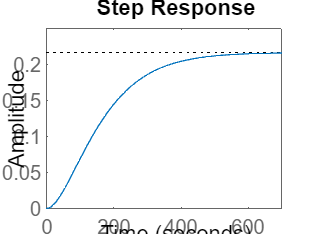

Gsss=Gs*Entrada_caudal;
u=step(Gs);
stepplot(Gsss,700)

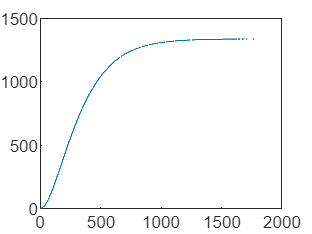

sizeof=length(u);
Time=0:1:sizeof-1;
plot(Time,u)

## Sintonización por Nichols

Pendiente

dt=Time(2)-Time(1)

dt = 1

dy=diff(u)/dt

dy =     0.0220
    0.0656
    0.1087
    0.1513
    0.1934
    0.2350
    0.2762
    0.3168
    0.3570
    0.3967


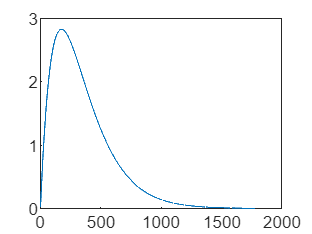

plot(Time(1:end-1),dy)

Punto de inflexión

[m  p]=max(dy)

m = 2.8233

p = 175

yp=u(p)

yp = 352.8645

tp=Time(p)

tp = 174

plot(Time,u)
hold on
plot(tp,yp,'ro')

Recta tangente

`y-yp=m(x-xp)`

taux=0:dt:600

taux =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


yaux=m*(taux-tp)+yp

yaux = 1.0e+03 *

   -0.1384   -0.1356   -0.1327   -0.1299   -0.1271   -0.1243   -0.1215   -0.1186   -0.1158   -0.1130   -0.1102   -0.1073   -0.1045   -0.1017   -0.0989   -0.0960   -0.0932   -0.0904   -0.0876   -0.0848   -0.0819   -0.0791   -0.0763   -0.0735   -0.0706   -0.0678   -0.0650   -0.0622   -0.0593   -0.0565   -0.0537   -0.0509   -0.0480   -0.0452   -0.0424   -0.0396   -0.0368   -0.0339   -0.0311   -0.0283   -0.0255   -0.0226   -0.0198   -0.0170   -0.0142   -0.0113   -0.0085   -0.0057   -0.0029   -0.0001


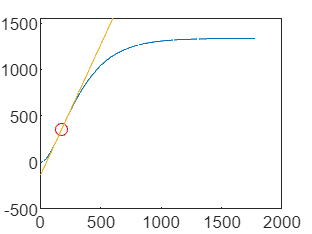

plot(taux,yaux)
grid on
hold off
grid off

Encontramos T y L

L=tp-(yp/m)

L = 49.0183

T_2=tp+(u(end)-yp)/m

T_2 = 521.8123

## Constantes 

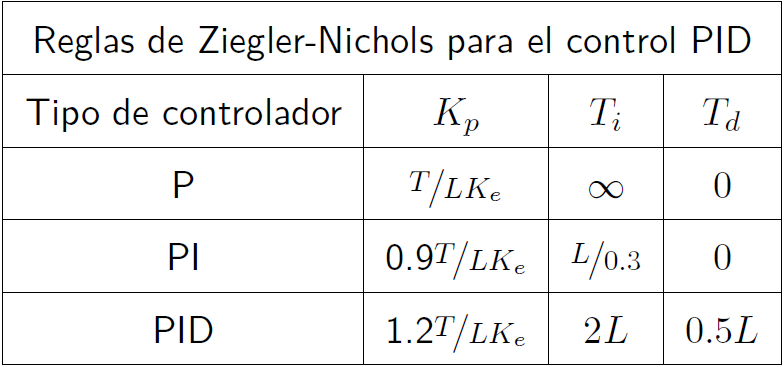

Para un controlador PI

Kp=(T_2/(L*Ke))

Kp = 0.0080

Ki=0

Ki = 0

Kd=0

Kd = 0

# FUNCIÓN DE TRANSFERENCIA RESULTANTE

PID=Kp+ Kd*tf([1 0],[1])+Ki*tf([1],[1,0]);
GT=Gs*PID/(1+Gs*PID)

GT =
 
            0.001406 s^2 + 3.233e-05 s + 1.858e-07
  ----------------------------------------------------------
  s^4 + 0.04598 s^3 + 0.002199 s^2 + 3.841e-05 s + 2.033e-07
 
Continuous-time transfer function.



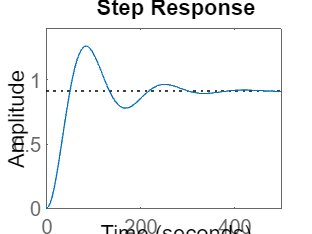

step(GT)

Calculo de resistencias

%Para el sumador restador: 4 de 100k
%Para el control P amplificador inversor: 
Res1=100^3;
Res2=Kp*Res1

Res2 = 7.9717e+03

%Para el amplificador inversor unitario: R=5k